# Lab 4 - Working with 'real' data

Thomas Conaway

Lab Partners: Avi Soval, Jeff Jiang

Time: 15 hours (including lab)

## Problem 1

We will be looking at data from a gamma-ray satellite in low Earth orbit. The satellite takes a reading of the number of particles detected every 100ms as it orbits the earth (approximately 90 minutes) and virtually all detections are from background cosmic rays. Metadata for each gamma-ray count is recorded, which includes time (in GPS seconds), solar phase and earth longitude (in degrees). Data was then collected over many orbits, resulting in the over 25 million recorded counts which we will now examine. 

clc; clear; close all;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:)

ans =    940680016         315          45          10


1) Exploration of the satellite data. Full plot contains many 90 minute intervals and is difficult to read, though we can at least see the gamma-ray count range from 0 to 30. For finer details, we will need to look at a shorter interval (only several orbits).

% Time (GPS seconds), Solar Phase (deg), Earth Longitude (deg), Particle Counts
% plot(mydata(:,1),mydata(:,4)); % much too large, slow to load
% title("Gamma-ray Counts Over Entire Run");
% xlabel("Time in GPS seconds");
% ylabel("Gamma-ray Count");

First, we'll will check the spacing between the data for any gaps.

max(diff(mydata(:,1))) % same time interval, every 100 ms, no gaps

ans = 0.1000

min(diff(mydata(:,1))) % no smaller time intervals or double counts

ans = 0.1000

max(diff(mydata(:,2))) % no gaps in solar phase

ans = 0.0071

max(diff(mydata(:,3))) % no gaps in orbital longitude

ans = 0.0067

Data has been faithfully collected every 100ms and sustains constant rates for the orbit and solar phase. Over the 90 minute orbit the satellite will record 10*60*90=54,000 counts.

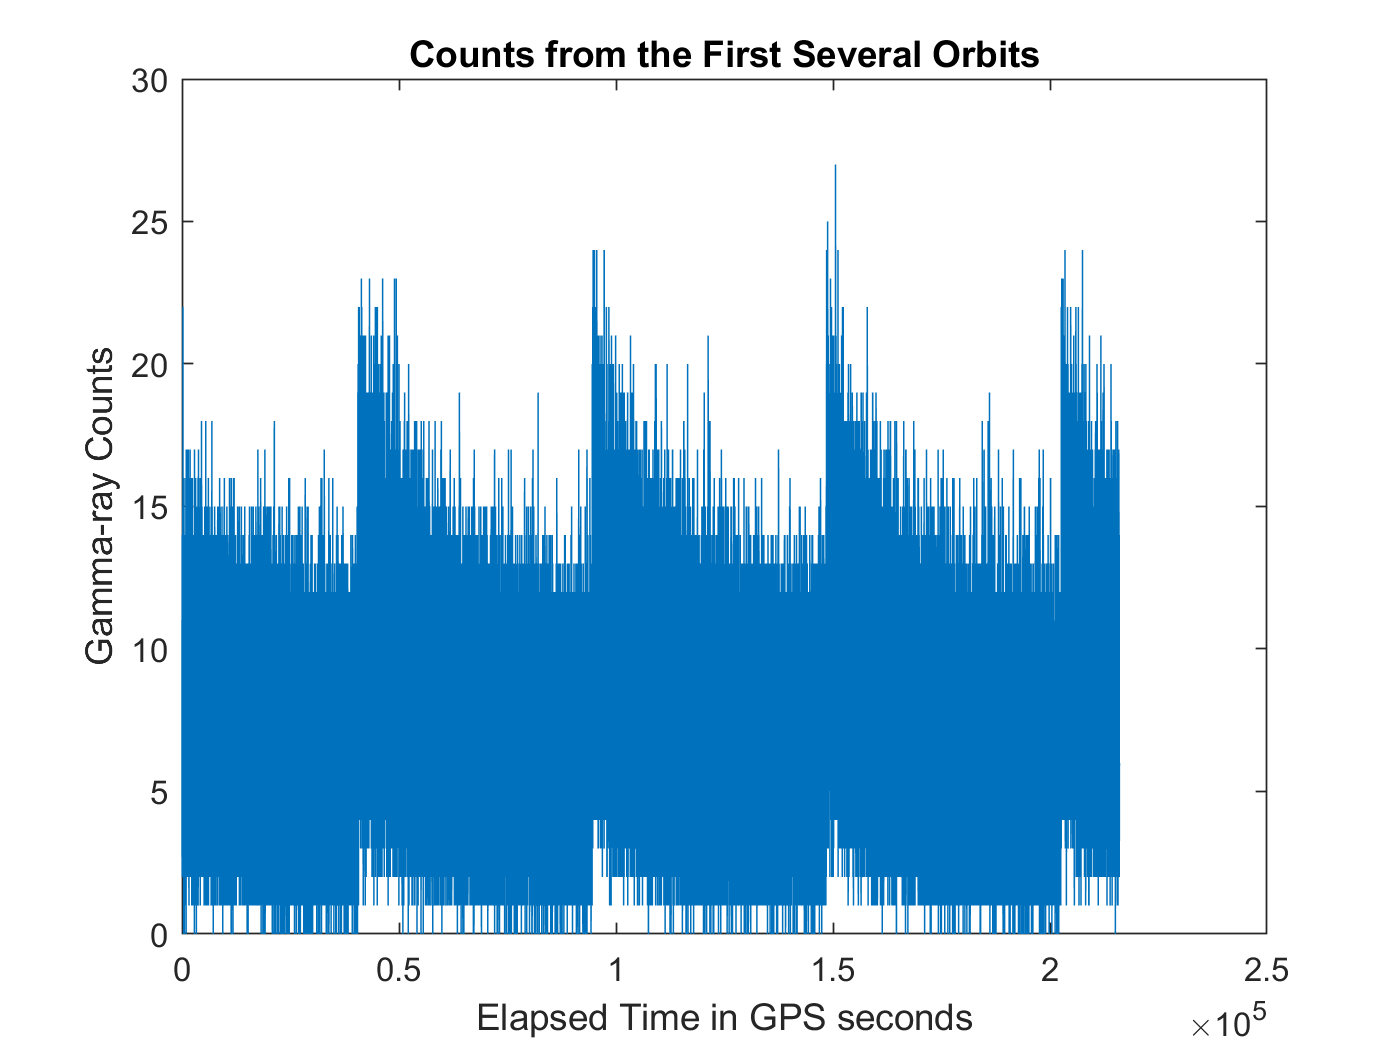

xrange = 1:(54000*4);
plot(xrange,mydata(xrange,4));
title("Counts from the First Several Orbits");
xlabel("Elapsed Time in GPS seconds");
ylabel("Gamma-ray Counts");

We can see sharp upward shifts in the average number of counts occurring roughly every 90 minutes. A closer inspection of this feature is required.

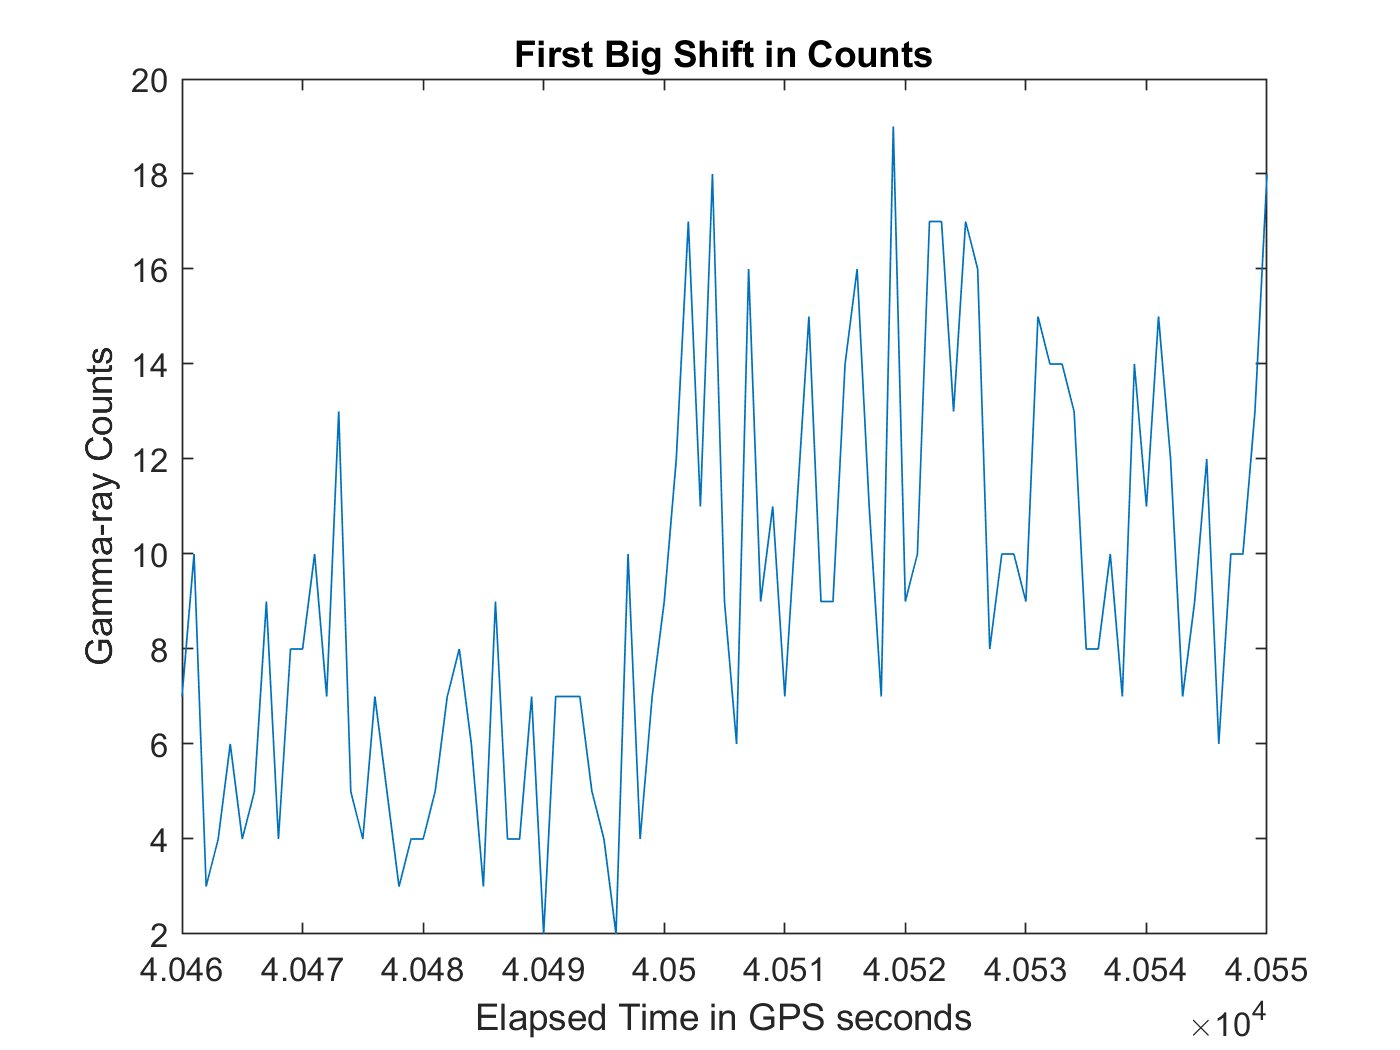

testrange1 = 40460:40550; % first big shift in counts
plot(testrange1,mydata(testrange1,4));
title("First Big Shift in Counts");
xlabel("Elapsed Time in GPS seconds");
ylabel("Gamma-ray Counts");

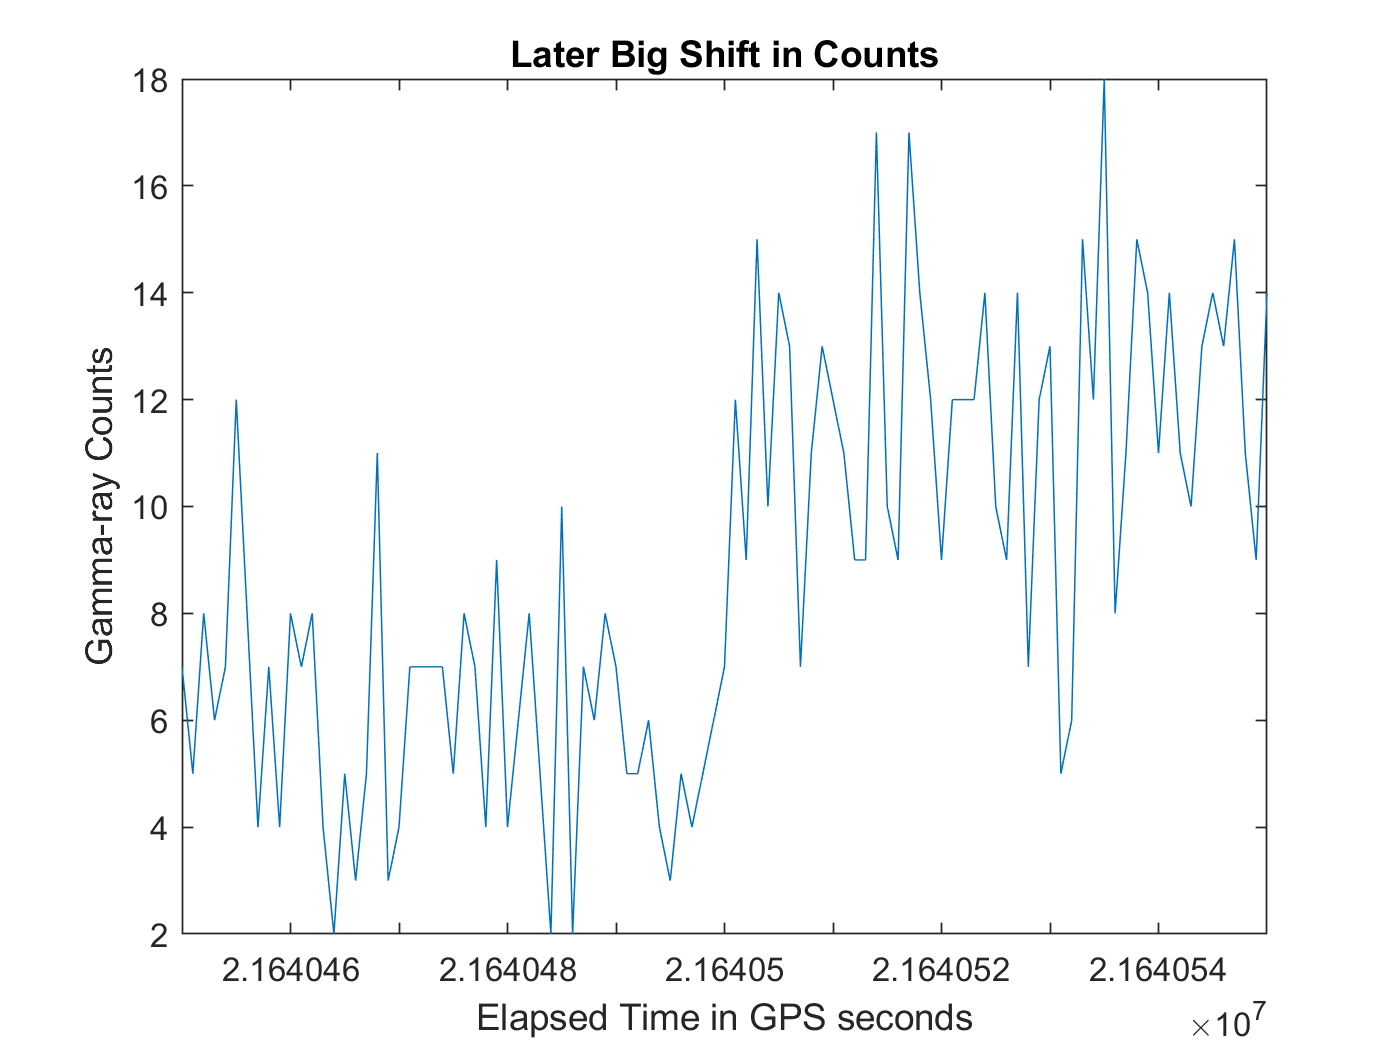

testrangeend = (54000*400+40450):(54000*400+40550); % checking for if it stays the same at larger times
plot(testrangeend,mydata(testrangeend,4));
title("Later Big Shift in Counts");
xlabel("Elapsed Time in GPS seconds");
ylabel("Gamma-ray Counts");

The shift looks like it is occurring at the exact same time / location. Looking at the metadata around this shows:

mydata(40501-3:40501+3,2:4)

ans =   243.0261  314.9800    4.0000
  243.0332  314.9867    7.0000
  243.0403  314.9933    9.0000
  243.0474  315.0000   12.0000
  243.0545  315.0067   17.0000
  243.0616  315.0133   11.0000
  243.0687  315.0200   18.0000


mydata(40501+54000*400-3:40501+54000*400+3,2:4)

ans =   148.3038  314.9800    5.0000
  148.3109  314.9867    6.0000
  148.3181  314.9933    7.0000
  148.3252  315.0000   12.0000
  148.3323  315.0067    9.0000
  148.3394  315.0133   15.0000
  148.3465  315.0200   10.0000


Sampling data around this point reveals that this feature starts at exactly 315 degrees longitude and repeats for every 90 minute interval at this position. The orbital period is exactly 90 minutes so it is both this exact position and time.

I will also check briefly the solar phase to compare counts over a sample 90 minutes for two sets, out of phase by 180 degrees.

indices = find(mydata(:,3)==315);
diff(mydata(indices(1:5),2)) % every 90 minutes the solar phase has moved 24.0632 degrees

ans =    24.0632
   24.0632
   24.0632
   24.0632


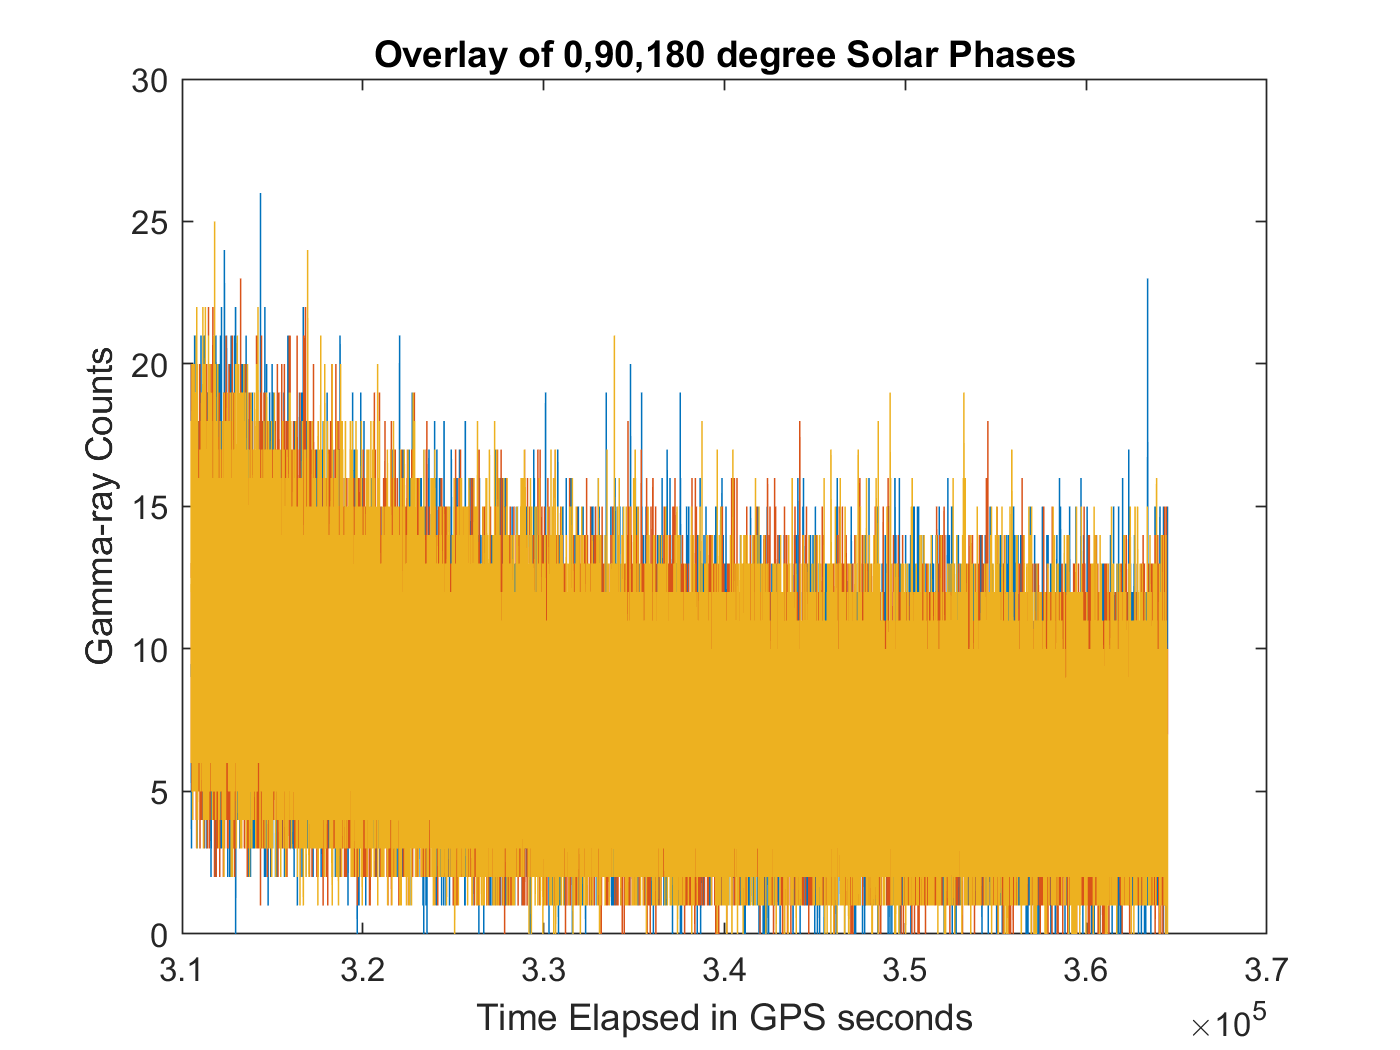

range1 = indices(6):indices(7); % roughly 0 degrees solar phase
range2 = indices(13):indices(14); % roughly 180 degrees
rangehalf = indices(9):indices(10); % roughly 90 degrees
plot(range1,mydata(range1,4));
title("Overlay of 0,90,180 degree Solar Phases");
xlabel("Time Elapsed in GPS seconds");
ylabel("Gamma-ray Counts");
hold on;
plot(range1,mydata(range2,4));
plot(range1,mydata(rangehalf,4));
hold off;

There does not appear to be a significant difference in the average count at different phases. This is to be expected as we know the sun does not emit significant gamma rays to earth except by solar flares.

Cosmic ray bursts are very rare but do occur about once a day. The gamma-ray satellite recorded data for nearly a month, so some signal contamination is to be expected. These signals are rare enough that they will not change the shape of the background pdf() when included with the background data.

Another concern for the background is the sudden sharp increase then decay in counts every 90 minutes which is highly unlikely to be a signal with this exact regularity and frequency. It may be the instruments that are doing this, so the background pdf() will have to accommodate this if it cannot be solved by other means.

2) As we've seen, the background does not stay consistent over the dataset (starts high, decays over 90 minutes, repeats). We will try to make this feature more visible by combining the orbits by averaging each count that occurs at the same 100ms interval within the 90 minute orbit. This should smooth out some of the noise.

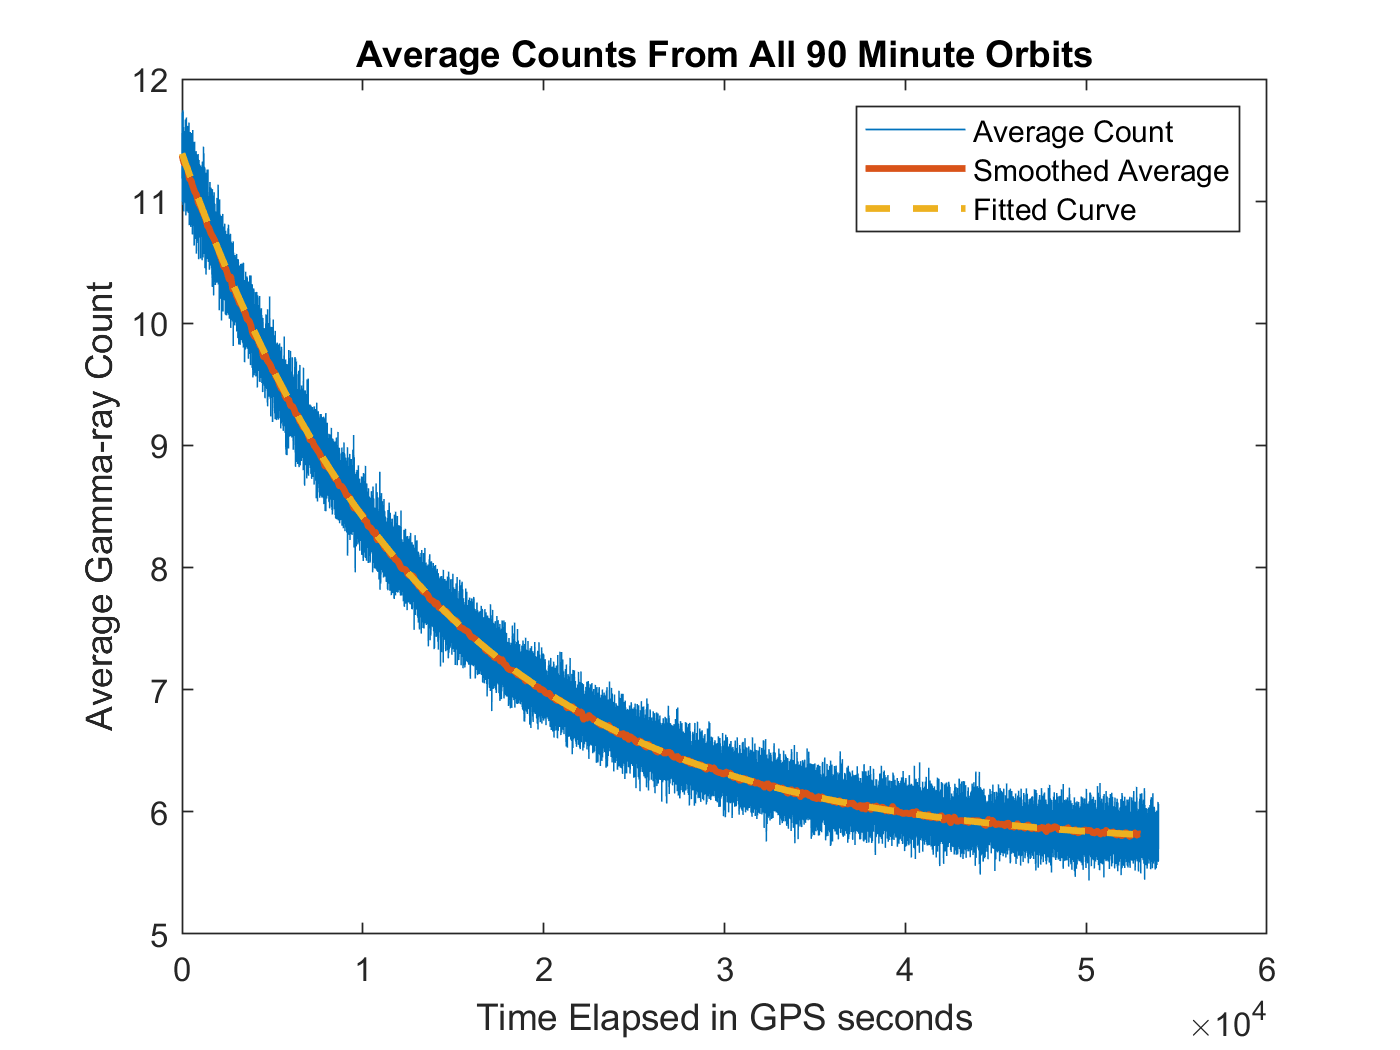

averagedata = mydata(indices(1):(indices(2))-1,4); % all counts in first complete 90 minute range
after315sample = mydata(indices(1)+0,4); % data from just after 315 deg
after315sample2 = mydata(indices(1)+10*60*60,4); % data 60 minutes after 315 deg

for k = 2:(length(indices)-1)
    averagedata = averagedata + mydata(indices(k):(indices(k+1))-1,4); % adding counts in next range
    after315sample = [after315sample;mydata(indices(k)+0,4)];
    after315sample2 = [after315sample2;mydata(indices(k)+10*60*60,4)];
end
averagedata = averagedata / k; % getting average at each point in range
averagerange = 1:length(averagedata);

plot(1:length(averagedata),averagedata); % fuzzy but narrower
title("Average Counts From All 90 Minute Orbits");
xlabel("Time Elapsed in GPS seconds");
ylabel("Average Gamma-ray Count");
hold on;
%bininterval = 0.1*10^4;
bininterval = 100; % for smoothing out the bumps
cruncheddata = [];
for j = 0:(53000/bininterval)
    cruncheddata = [cruncheddata,mean(averagedata((1+j*bininterval):((1+j)*bininterval)-1,1))];
end
crunchx = 1:bininterval:length(cruncheddata)*bininterval;
plot(crunchx,cruncheddata,"LineWidth",2); % looking more like a line now

% curve fitting app used here with averagerange for x, averagedata for y,
% exponential curve with 2 terms.

fun = @(t) 5.716*exp(-7.361e-05*t) + 5.674*exp(7.763e-08*t); % no bins
%fun = @(t) 5.697*exp(-7.358e-05*t) + 5.673*exp(8.363e-08*t); % 100 bin
%fun = @(t) 5.551*exp(-7.362e-05*t) + 5.675*exp(7.629e-08*t); % 1000 bin
ytest = fun(crunchx);
plot(crunchx,ytest,'LineStyle','--',"LineWidth",2);
legend("Average Count","Smoothed Average","Fitted Curve");
hold off;

3) The time dependence for the mean rate can be found by averaging short intervals of the counts from each 90 minute period and fitting an exponential decay curve using the MATLAB "Curve Fitting" app. This function for the curve allows us to conjure the mean rate parameter needed to create a background model for the time of our choosing within the 90 minute interval. Here are some sample histograms with our Poisson PDFs (chosen because we are examining the average rate of counts) generated this way to demonstrate how well this time-dependent background models our data:

histogram(after315sample,"Normalization","pdf");
fun(1)

ans = 11.3896

mean(after315sample)

ans = 11.1837

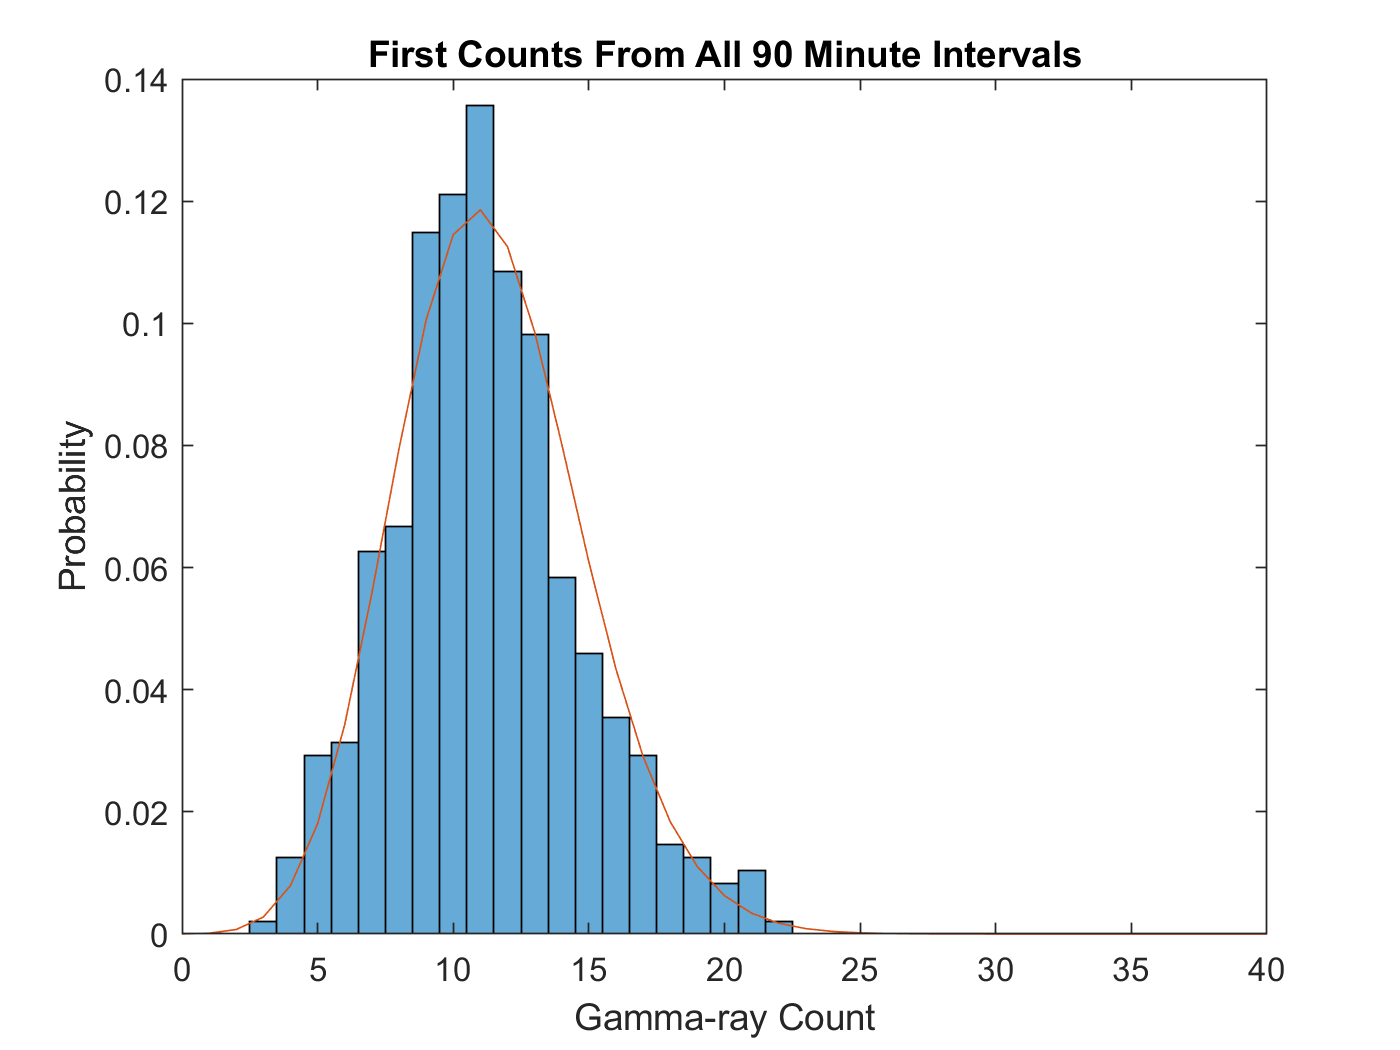

testdist = makedist("Poisson","lambda",fun(1));
mydist = pdf(testdist,0:40);
hold on;
plot(0:40,mydist);
title("First Counts From All 90 Minute Intervals");
xlabel("Gamma-ray Count");
ylabel("Probability");
hold off;


histogram(after315sample2,"Normalization","pdf");
title("60 Minute Counts From All 90 Minute Intervals");
xlabel("Gamma-ray Count");
ylabel("Probability");
fun(10*60*60)

ans = 6.0937

mean(after315sample2)

ans = 6.1921

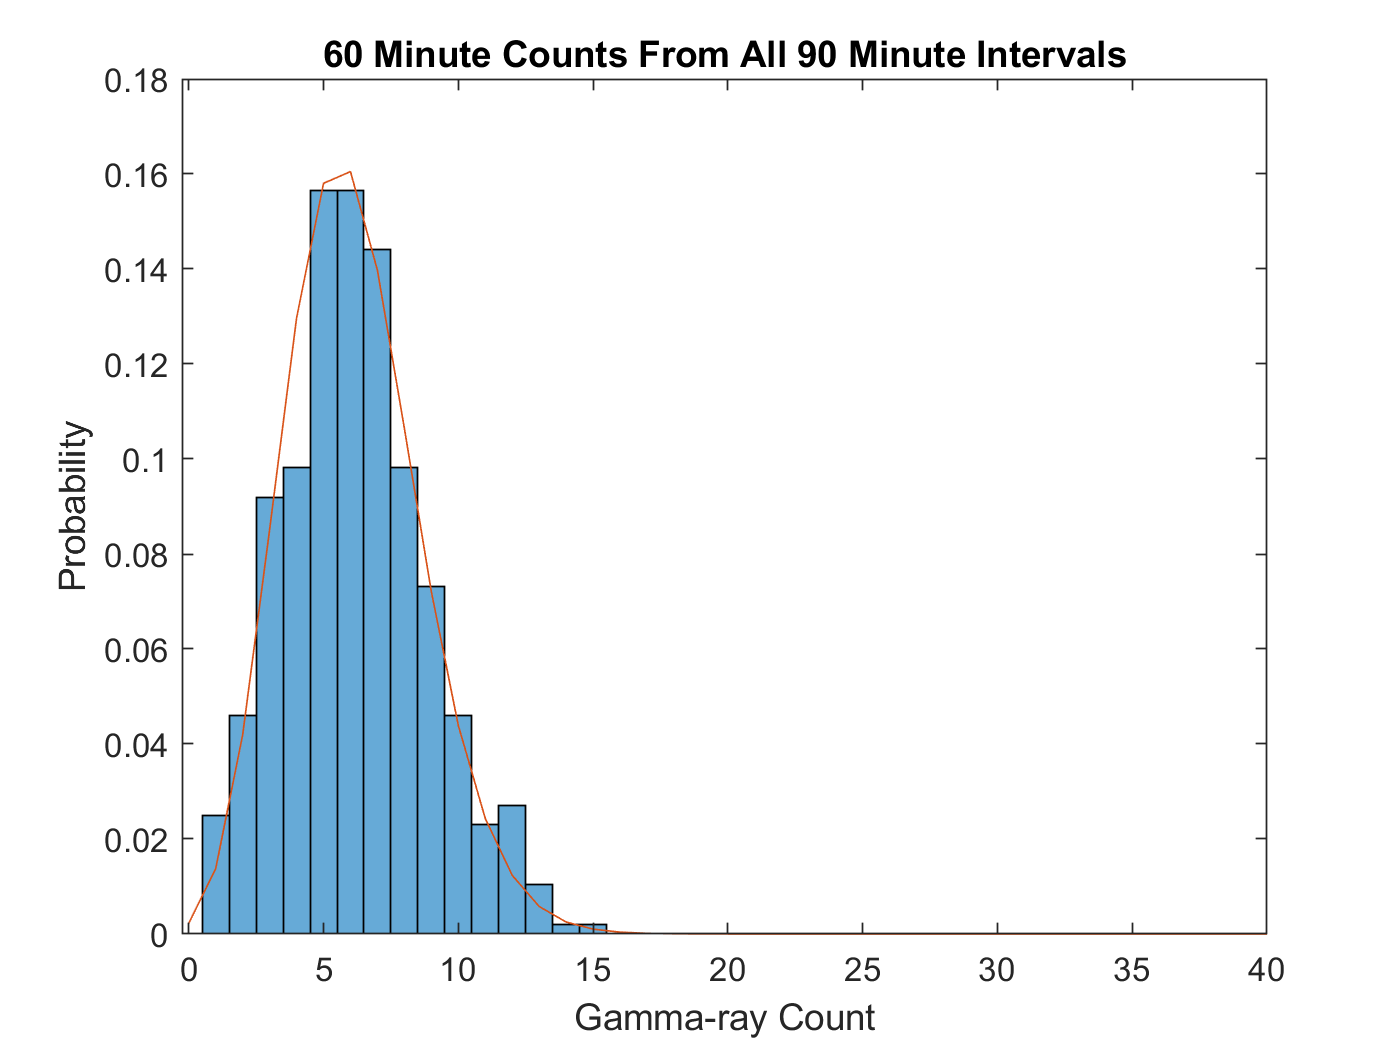

testdist2 = makedist("Poisson","lambda",fun(10*60*60));
mydist2 = pdf(testdist2,0:40);
hold on;
plot(0:40,mydist2);
hold off;

The time-dependent mean is not an exact match for the histogram mean but it comes very close. Histogrammed counts also follow the curve of the model. The model is good but not perfect.

4) A varying background results in different thresholds for discovery sensitivity. For backgrounds early in the 90 minute interval the mean rate is larger, meaning both the mean and the standard deviation (width, square root of mean) is larger. The '5 sigma' threshold for 100 millisecond gamma ray bursts is larger for earlier times than it is for later ones in this 90 minute orbital period. Here are some sample thresholds:

fivesigma = 1/(3500000);
backgroundthresholds = zeros(2,11);
backgroundthresholds(1,:) = [1:5400:54000,53999];
for k = 1:10
    backgroundthresholds(2,k) = icdf("Poisson",1-fivesigma,fun(1+(k-1)*5400));
end
backgroundthresholds(2,11) = icdf("Poisson",1-fivesigma,fun(54000-1));
table(backgroundthresholds,'RowNames',{'time (0.1 gps seconds)';'5 sigma threshold'})

ans = 2×1 table
                          backgroundthresholds
                          ____________________

    time (gps seconds)       [1x11 double]    
    5 sigma threshold        [1x11 double]    


Optional:

I feel that the variable background is caused by a feature of the satellite and not an exactly periodic spike and decay in gamma-ray production. I suspect that it is the result of orbital decay due to the satellite experiencing drag from collisions with particles in the low orbit atmosphere. As it loses altitude there is more atmosphere above to shield against cosmic radiation, and so the rate of counts lowers over time. Every 90 minutes the satellite propels itself back to its original altitude. Because this is only a simplified simulation of data, this occurs instantly.

My lab partner suggested that this may be the South Atlantic Anomaly (a region of the atmosphere with high radiation owing to the shape of the Earth's magnetic field), but the shape and extent of the SAA does not match the trend in the data. If it did, it would climb gradually instead of instantly jumping and would vary for a fraction of the 90 minutes instead of decaying over this time.

## Problem 2

We will be looking at a stack of simulated telescope images of stars. I will be looking for the faintest stars while my partner will be looking for a transient that occurs in one image (like a supernova).

1) Downloading the data. Loaded into MATLAB as 10 square 200 pixel images in 10x200x200 array. 

clc; clear; close all; close all hidden;
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata2 = h5read("images.h5",'/imagestack');

2) Exploring the data. I'll start by displaying the images in multiple forms and searching for interesting features.

oneimage = squeeze(mydata2(1,:,:));
brightestsignal = max(max(max(mydata2)))

brightestsignal = 47.7901

darkestsignal = min(min(min(mydata2))) % not zero, so zero may not be 'no signal'

darkestsignal = -2.7093

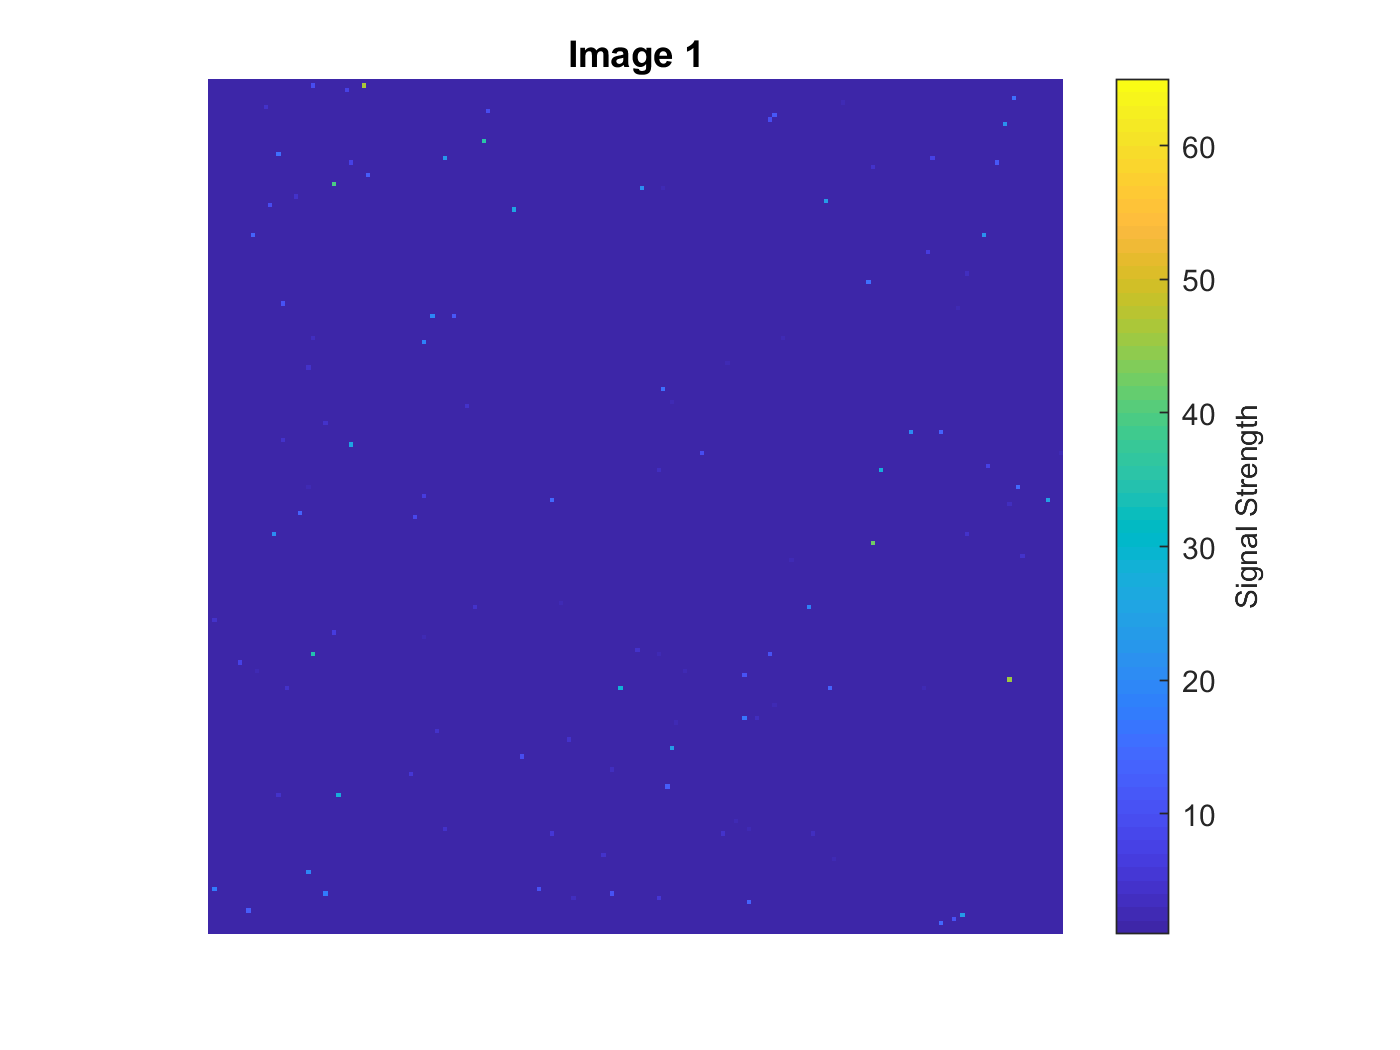

image(oneimage)
title("Image 1");
hold on;
h = colorbar;
ylabel(h, 'Signal Strength')
axis square;
axis off;
hold off;

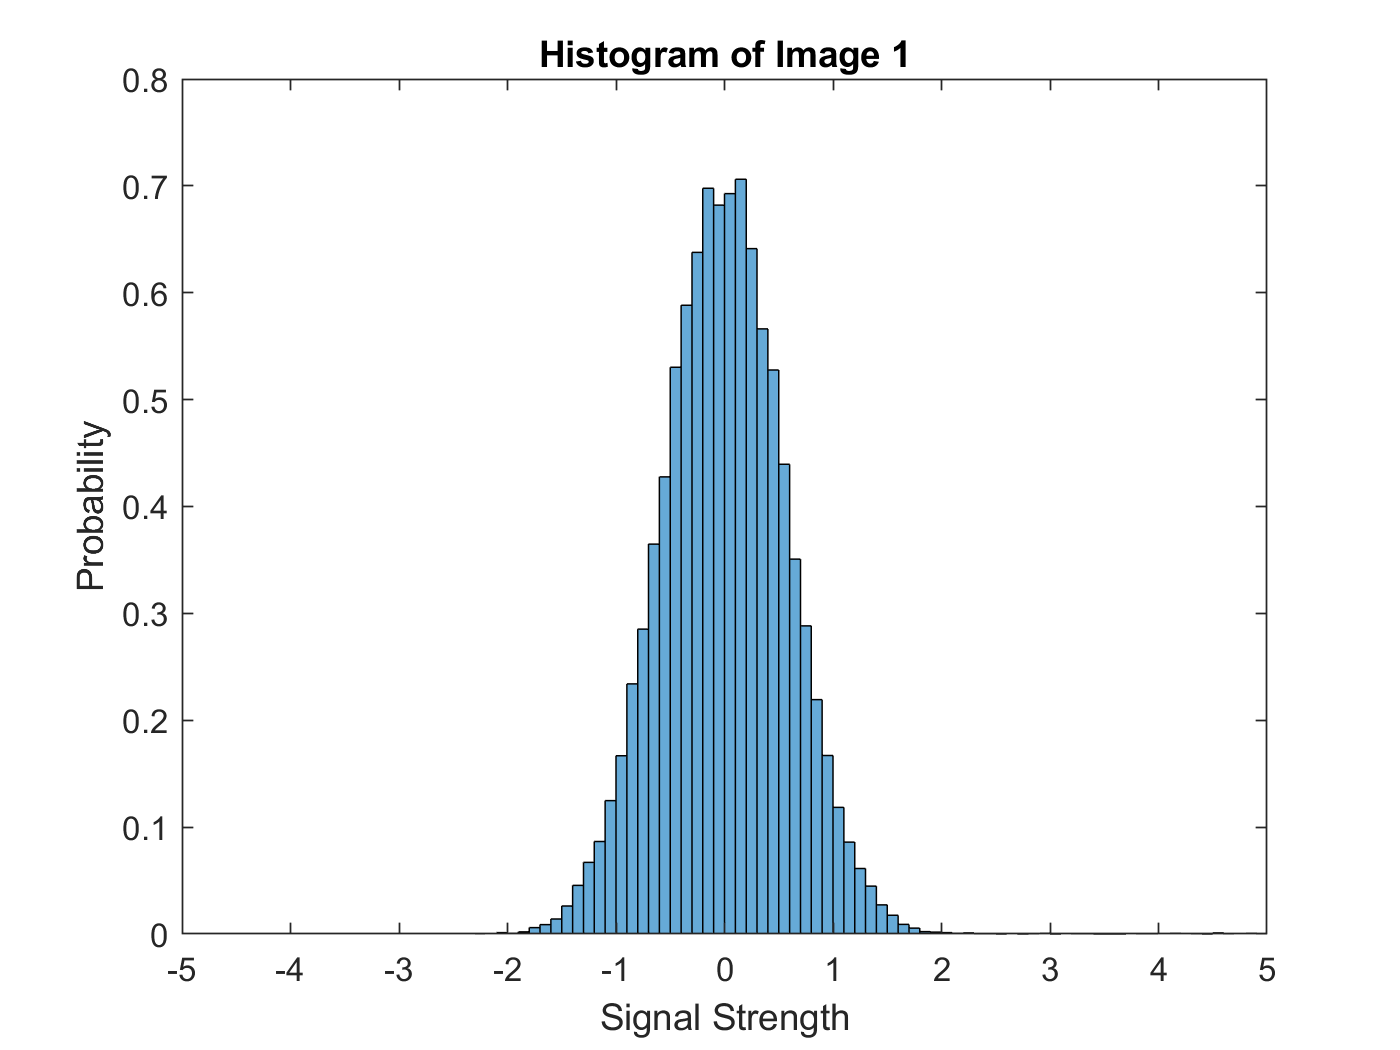

histogram(oneimage,"Normalization","pdf");
title("Histogram of Image 1");
xlabel("Signal Strength");
ylabel("Probability");
xlim([-5,5]);

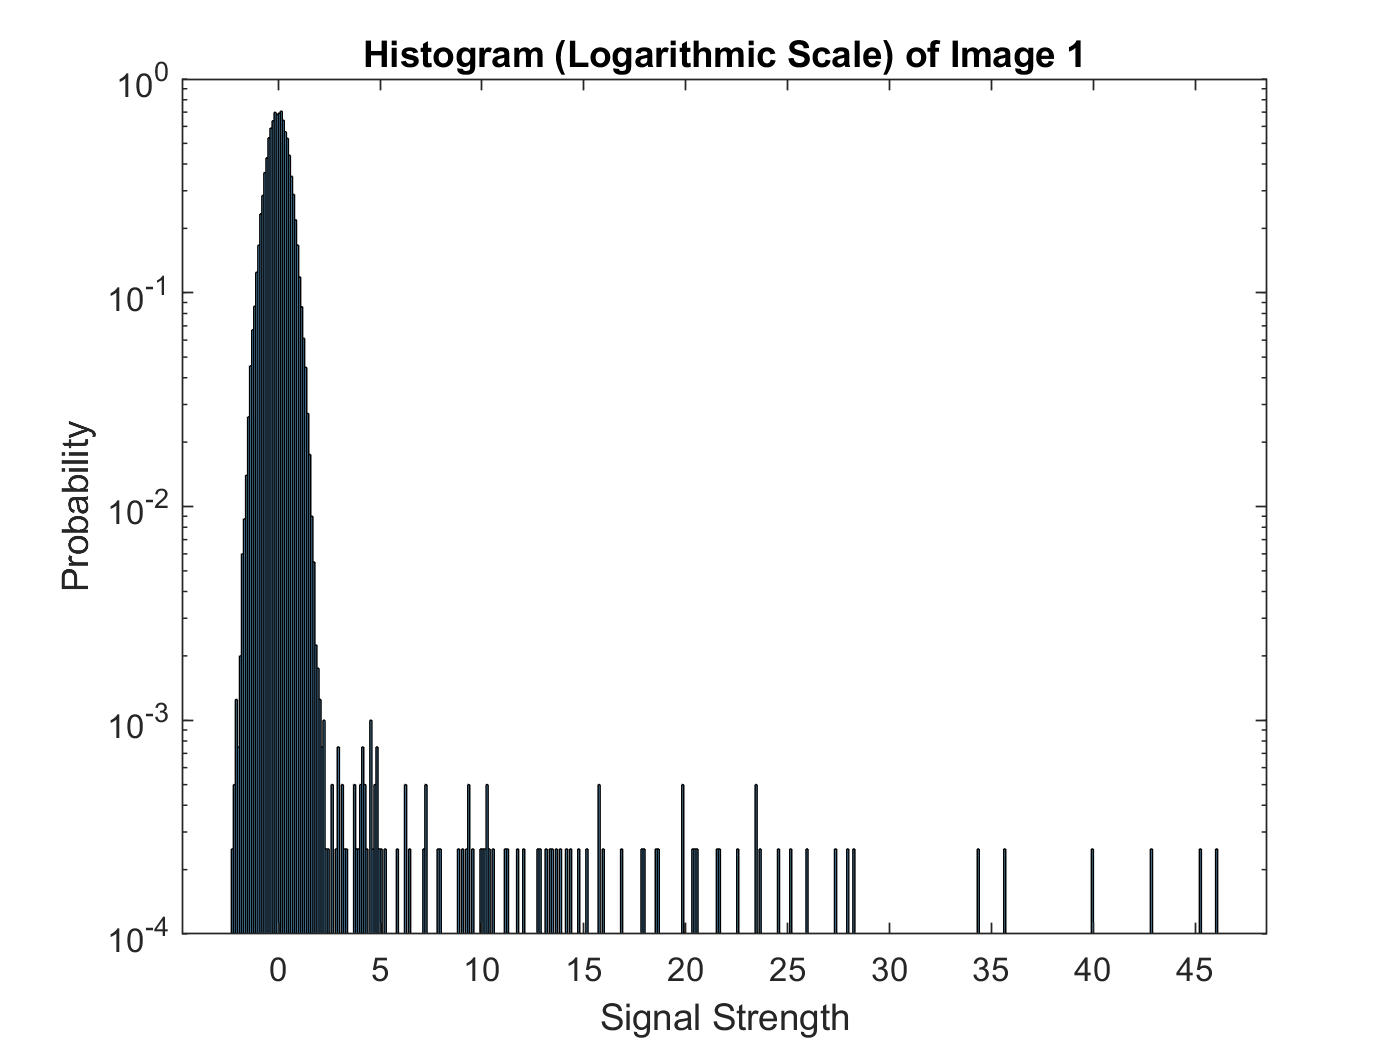

histogram(oneimage,"Normalization","pdf");
title("Histogram (Logarithmic Scale) of Image 1");
xlabel("Signal Strength");
ylabel("Probability");
set(gca,'YScale','log');

The bulk of the pixel values form a bell-shaped histogram centered at 0. Strong signals appear as bright dots in the image and as values out in the tail of the logscale histogram.

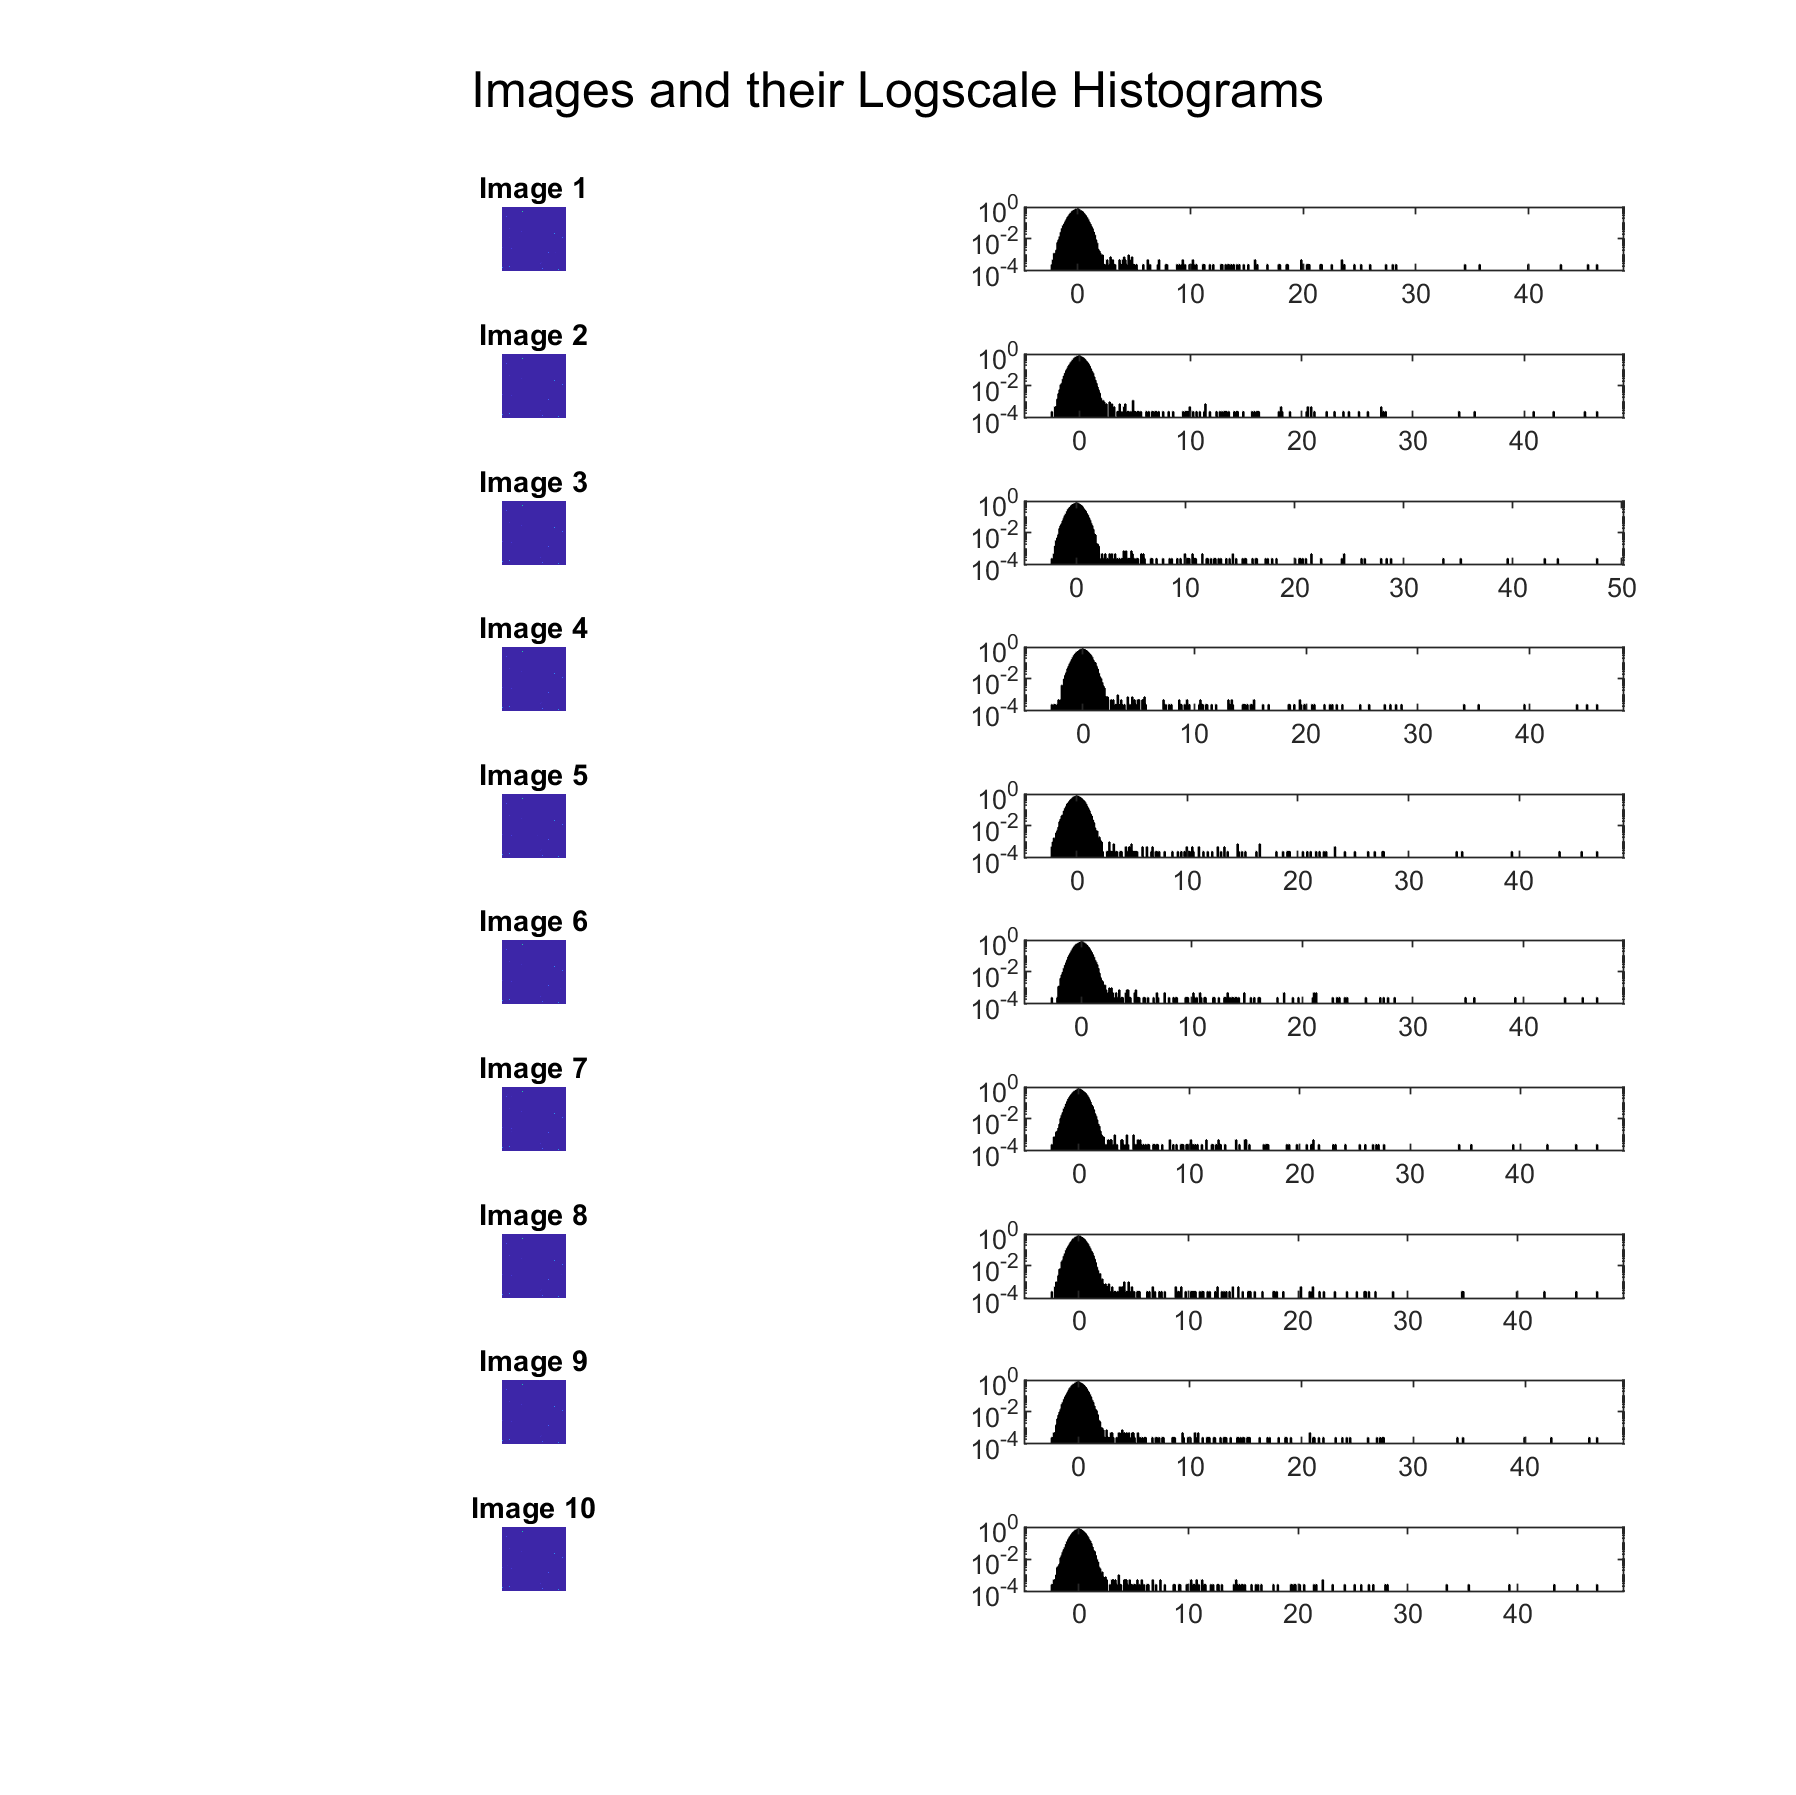

figure1 = figure('Position', [0, 0, 1000, 1000]);
for k = 1:10
    oneimage = squeeze(mydata2(k,:,:));
    subplot(10,2,k*2-1);
    image(oneimage);
    axis square;
    title("Image " + k);
    axis off;
    subplot(10,2,k*2);
    histogram(oneimage,"Normalization","pdf");
    set(gca,'YScale','log');
end
sgtitle("Images and their Logscale Histograms");

To the eye, each image on its own is indistinguishable from the others. The bright spots in each image are our signals (stars or such other phenomena) and may contaminate the background if included.

From the histograms for each image, we see that the background bulk of the data keeps its shape and remains centered at 0, and so is likely not time dependent. There are only 10 time samples for each pixel and their values experience small random fluctuations with no clear trend:

mydata2(:,1,1).'

ans =    -0.5049    0.2498   -0.5041   -0.7200    0.1023   -0.1137    0.8511   -0.0621    1.1984   -0.5545


mydata2(:,1,2).'

ans =    -0.2529    0.4002   -0.3043   -0.0301    1.7341   -0.5403    0.6642   -0.4426    1.0316    0.0969


mydata2(:,1,3).'

ans =     0.8267   -1.0960   -1.1571    0.3666   -0.1733   -0.3674    0.1470   -0.0057   -0.5096   -0.3376


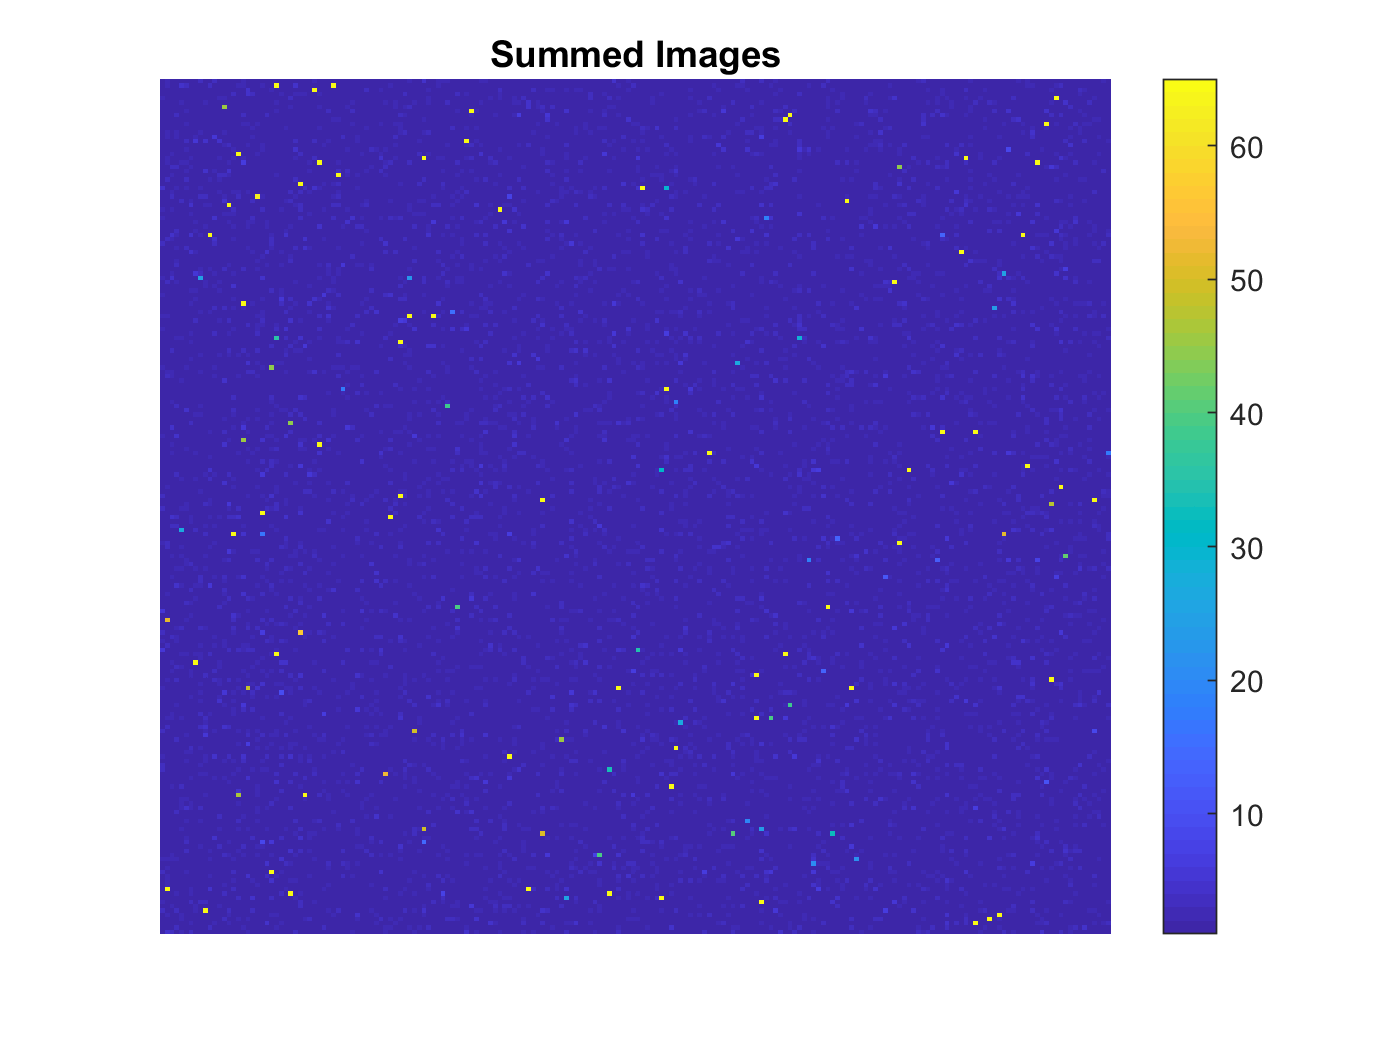

close all hidden; % fixed issue with subplot command
sumimg = zeros(200); % adding images together.
for k = 1:10
    sumimg = sumimg + squeeze(mydata2(k,:,:));
end
image(sumimg)
title("Summed Images");
axis off;
colorbar

The images appear to be spacially consistent, otherwise there would be trails left by the stars moving between images. We can also see faint signals begin to emerge from the background. Some of these are faint stars, but others may be brief fluctuations in either the background or from transients. They may also be anomalous data (errors) that could be further contaminating the signal.

To begin building the background I'd like to examine data from pixels where I'm fairly certain nothing resides. In the summed image I suspect these will be the pixels that have remained close to 0. I'll pick a lower limit for the signal strength based image histogram widths above (about 2.5) and see how many pixels are left available to use.

min(min(sumimg)) % has grown, may be a concern, some pixels are consistently low

ans = -7.1336

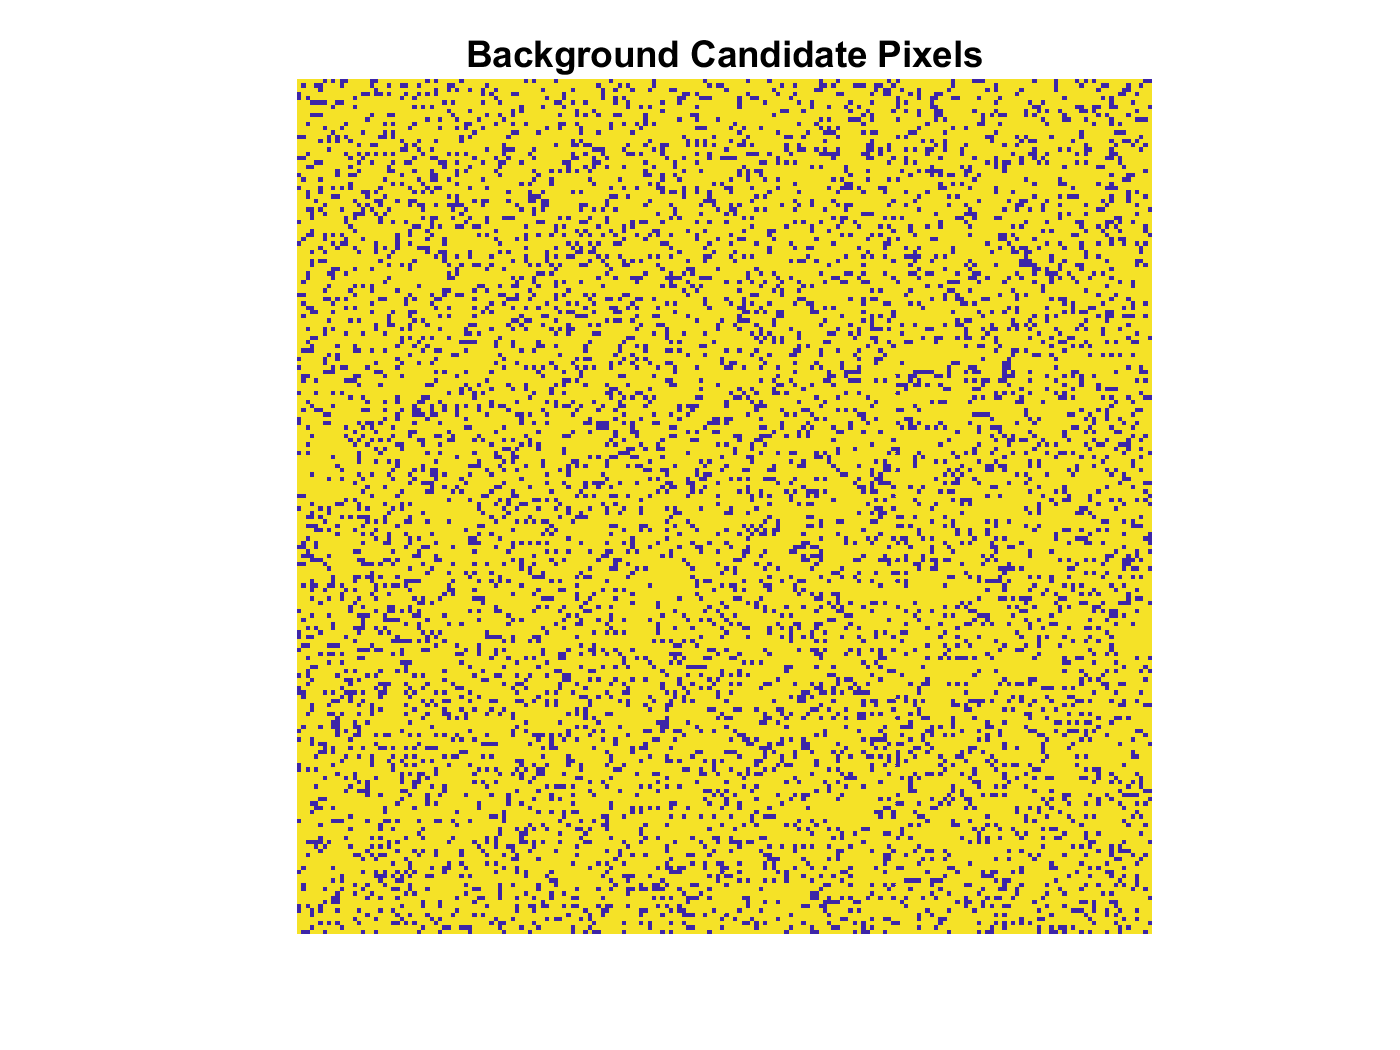

bgcandidates = zeros(200);
for k = 1:200
    for j = 1:200
        if abs(sumimg(k,j)) < 2.5 % abs(darkestsignal) % play around with this condition. see what shows up.
            bgcandidates(k,j) = 1;
        end
    end
end
image(bgcandidates*60); % scaled to show up as yellow
title("Background Candidate Pixels");
axis square;
axis off;

(sum(sum(bgcandidates)) / (200 * 200)) * 100 % getting the percent of usable pixels

ans = 83.8750

With these positions for likely background pixels I can generate the background for single images and/or all 10 images together.

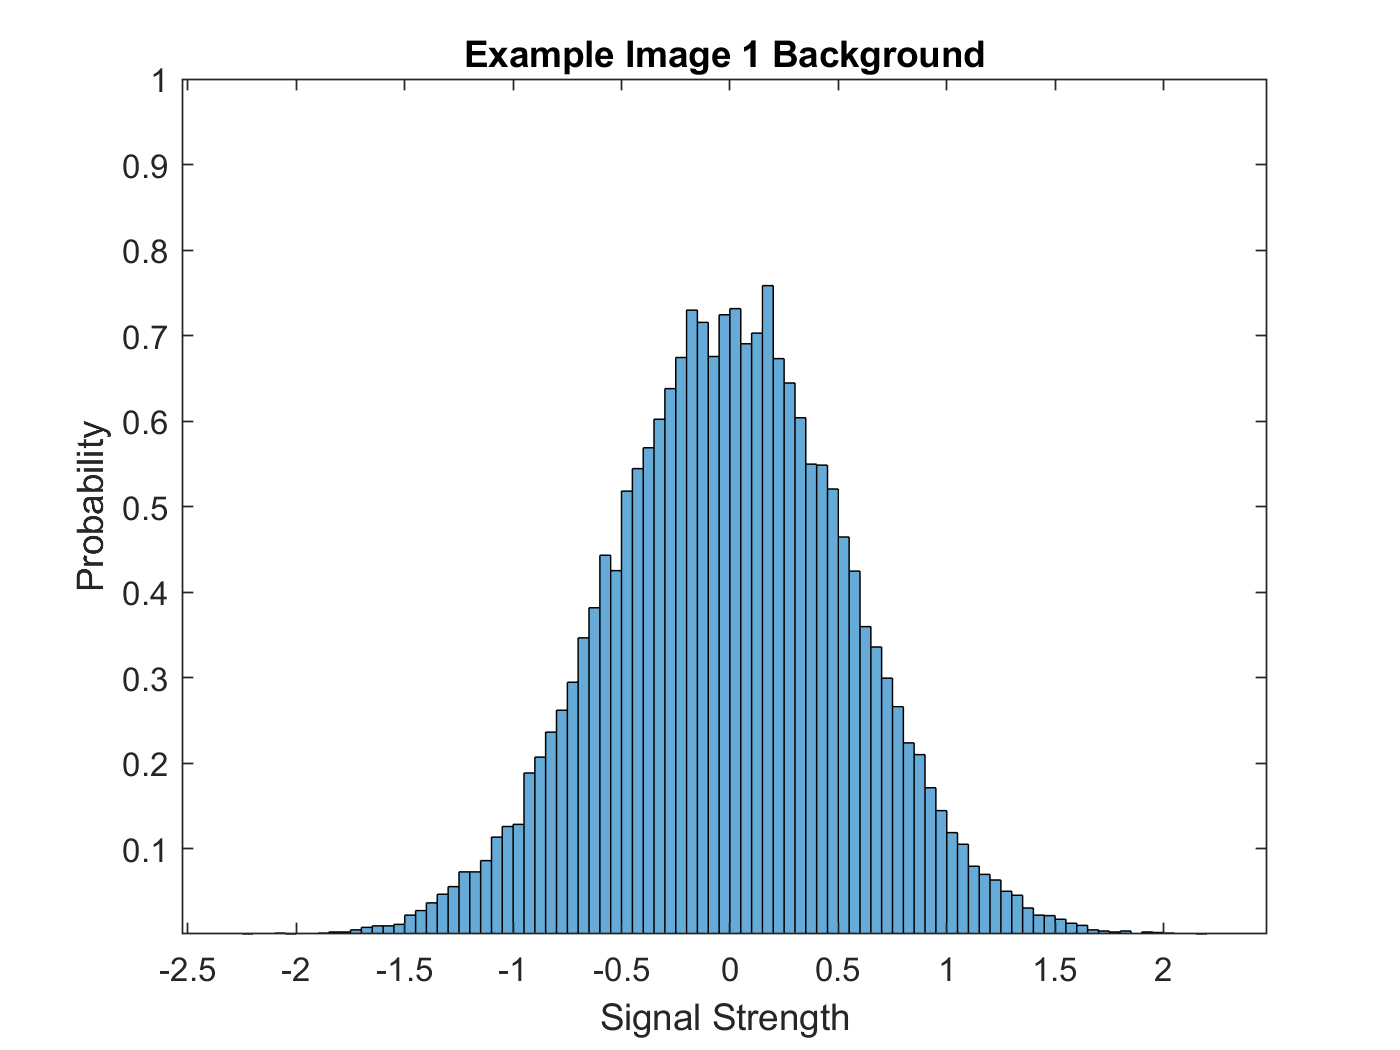

time1bg = [];
for k = 1:200
    for j = 1:200
        if bgcandidates(k,j) ~= 0
            time1bg = [time1bg,mydata2(1,k,j)];
        end
    end
end
histogram(time1bg,"Normalization","pdf");
title("Example Image 1 Background");
xlabel("Signal Strength");
ylabel("Probability");
ylim([10^-5,1]);

% set(gca,'YScale','log'); %

% takes time to run if there are many background pixels.
backgrounddata = [];
for k = 1:200
    for j = 1:200
        if bgcandidates(k,j) == 1
            backgrounddata = [backgrounddata; squeeze(mydata2(:,k,j))];
        end
    end
end

histogram(backgrounddata,"Normalization","pdf");
hold on;
title("Background from all Images");
bgfullmean = mean(backgrounddata)

bgfullmean = -1.3161e-04

bgfullstd = std(backgrounddata)

bgfullstd = 0.5464

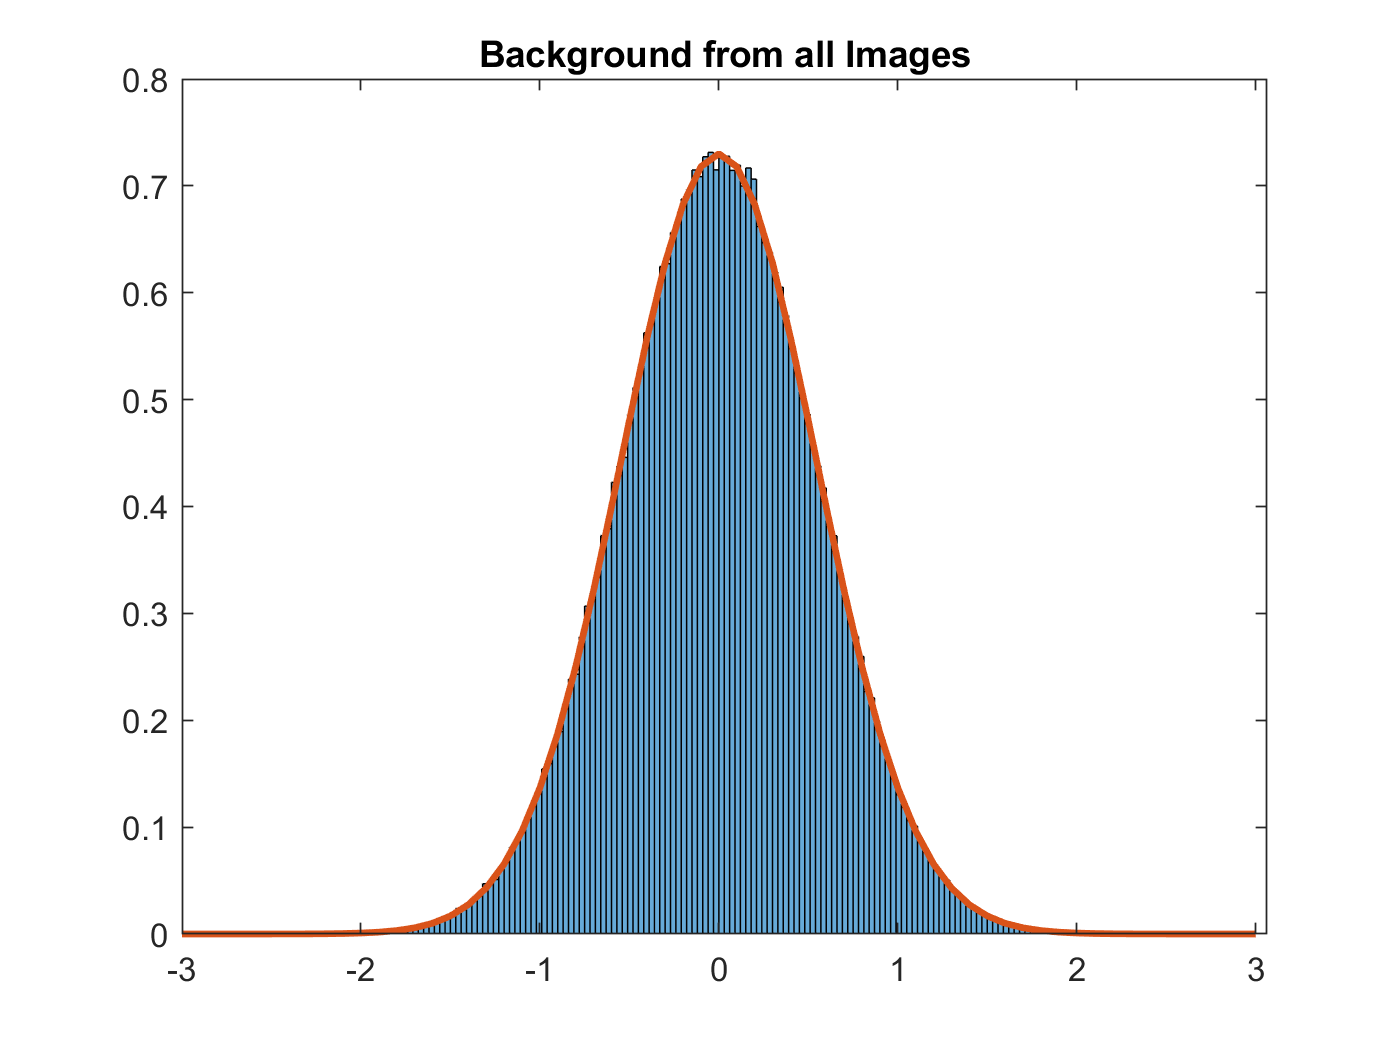

bgfulldist = makedist("Normal","mu",bgfullmean,"sigma",bgfullstd);
bgfullpdf = pdf(bgfulldist,-3:0.1:3);
plot(-3:0.1:3,bgfullpdf,"LineWidth",2);
% set(gca,'YScale','log'); %
hold off;

Background appears Gaussian, centered at zero, with a standard deviation of about 0.54 to 0.55 (slight variations depending on choice of background pixels).

3) Signal hunt. The signals I am searching for (faint stars) will appear faintly on the summed image. The faintest stars will be the ones that skirt most closely to the threshold set by the background PDF, which let's set to be '5 sigma'.

fivesigma = bgfullstd * 5

fivesigma = 2.7320

signals = zeros(200);
for k = 1:200
    for j = 1:200
        if sumimg(k,j) >= fivesigma
            signals(k,j) = sumimg(k,j);
        end
    end
end
faintstarnum = 50;
testhuntvalue = mink(signals(signals>0),faintstarnum); % finds the signal values closest to 5 sigma
min(testhuntvalue)

ans = 2.7324

max(testhuntvalue)

ans = 2.7501

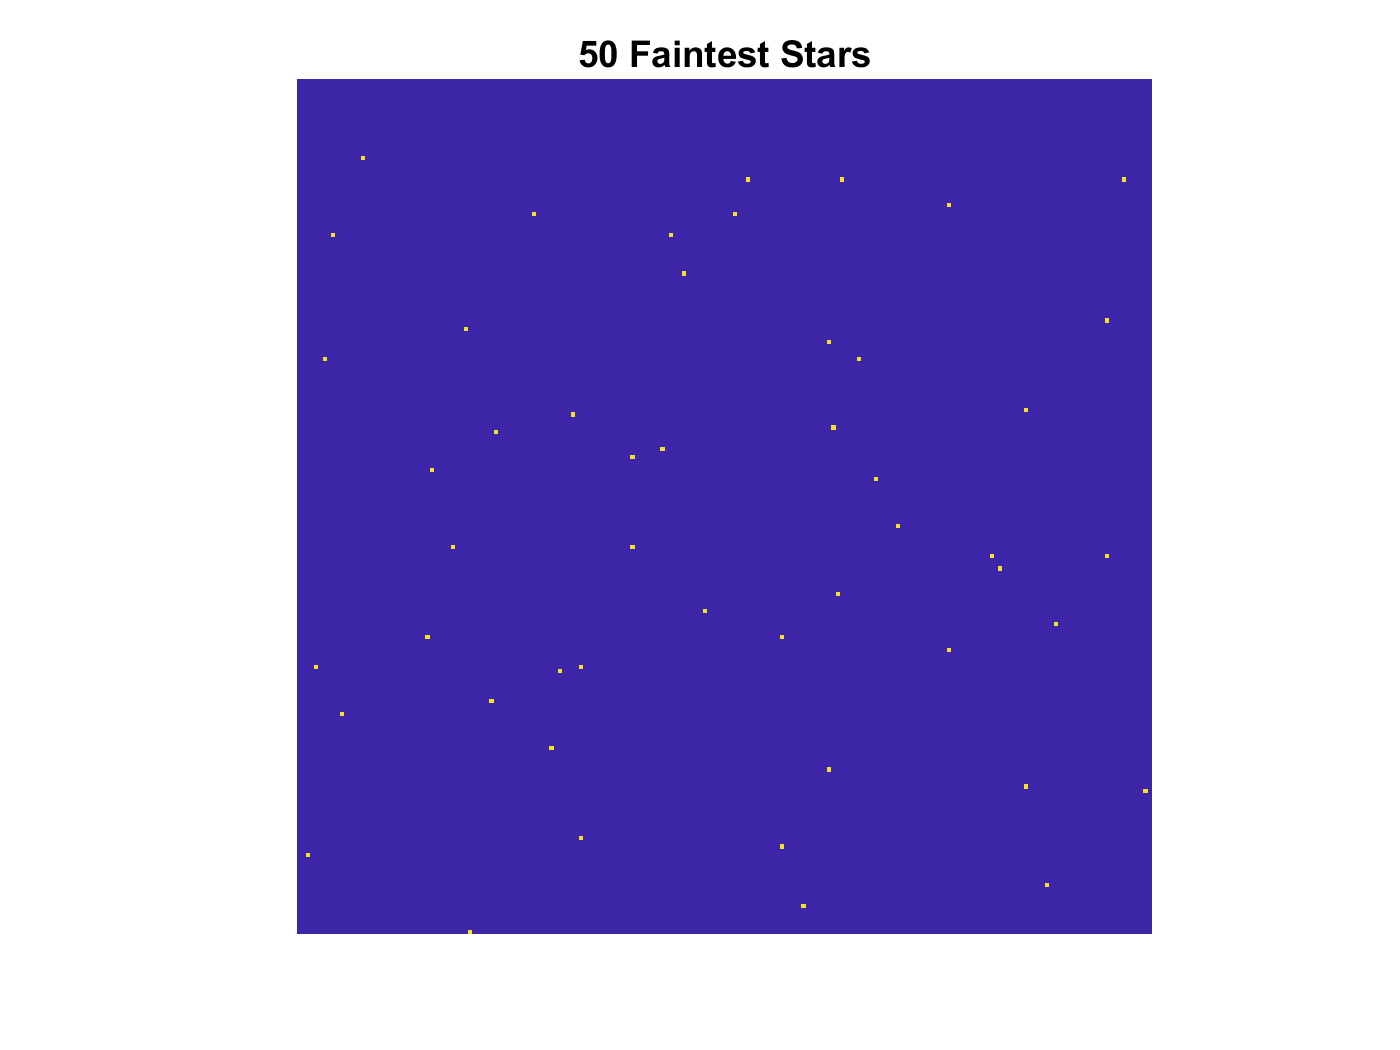

fainteststars = zeros(200);
for k = 1:faintstarnum
    [huntrow,huntcol] = find(sumimg == testhuntvalue(k,1)); % finds the location of the faintest signals
    fainteststars(huntrow,huntcol) = 1;
end
image(fainteststars*60)
title(faintstarnum + " Faintest Stars");
axis off;
axis square;

The faintest stars do not appear to be completely random in their placement. Playing with the number slider for how many to display shows that they are not present in some regions, and form 'strings' with other faint stars.

4) Pending results from lab partner. Partner is looking for the transient that appears in one image. His PDF will perhaps be modelled on the fluctuations in value for each of the pixels. His distribution won't be the same as mine because we asked different statistical questions of the same data which resulted in him examining a different background (variation in pixel value) versus mine (proximity to the no signal background).

EXTRA: My own experimentation with the search for the transient signal.

singlepixeldata = squeeze(mydata2(:,1,1));
maxdiff = zeros(200);
max(singlepixeldata) - min(singlepixeldata)

ans = 1.9184

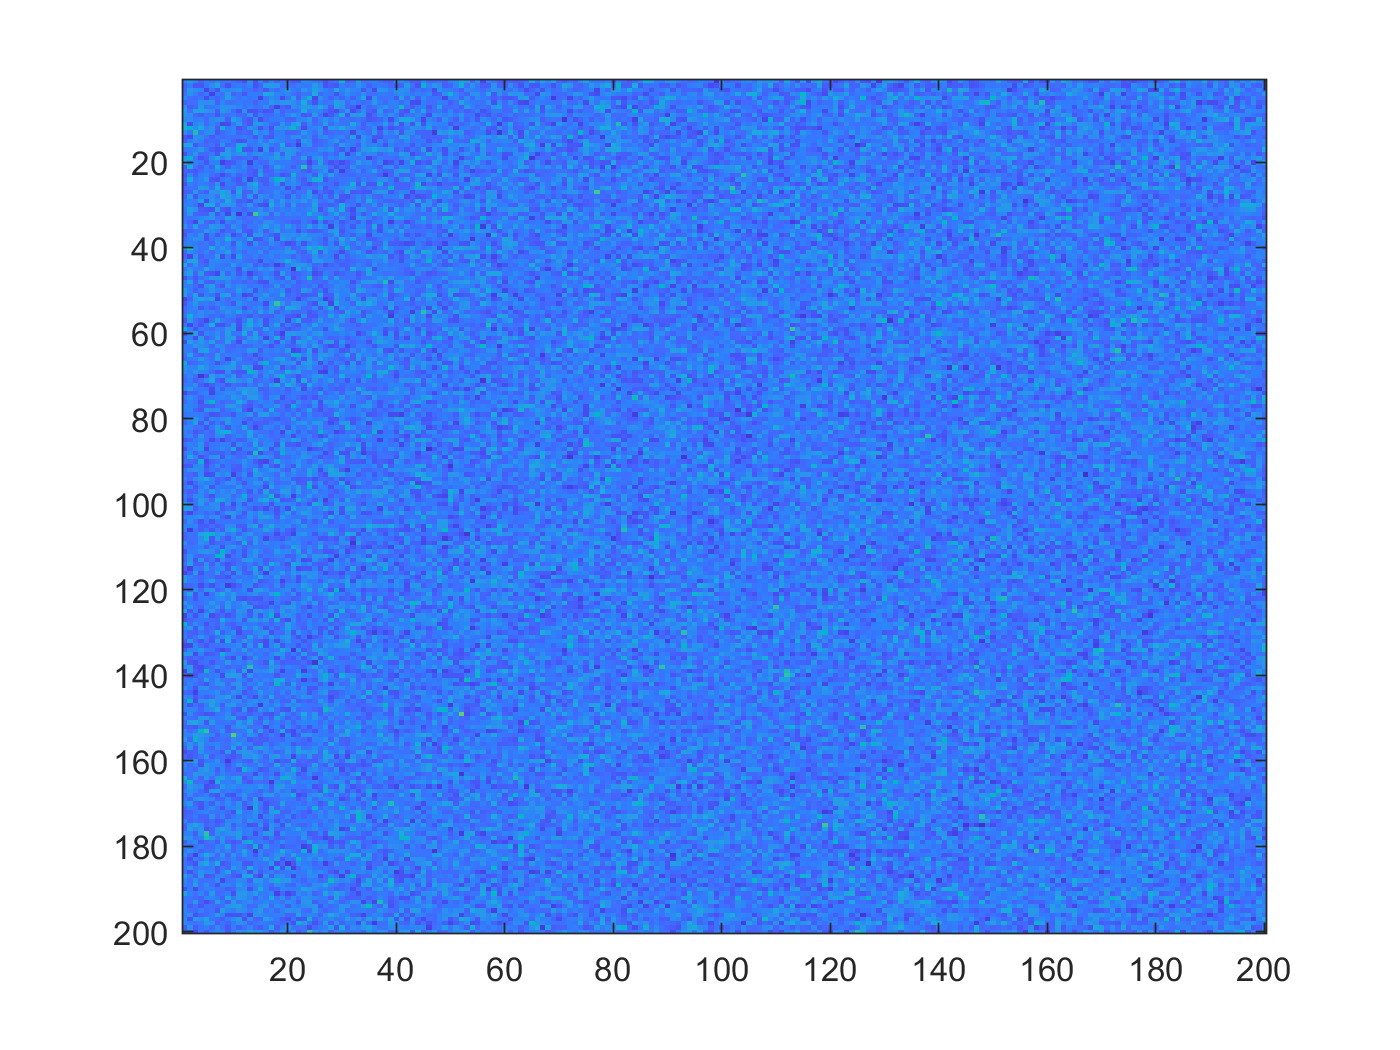

for k = 1:200
    for j = 1:200
        singlepixeldata = squeeze(mydata2(:,k,j));
        maxdiff(k,j) = max(singlepixeldata) - min(singlepixeldata);
    end
end
image(maxdiff.*10)

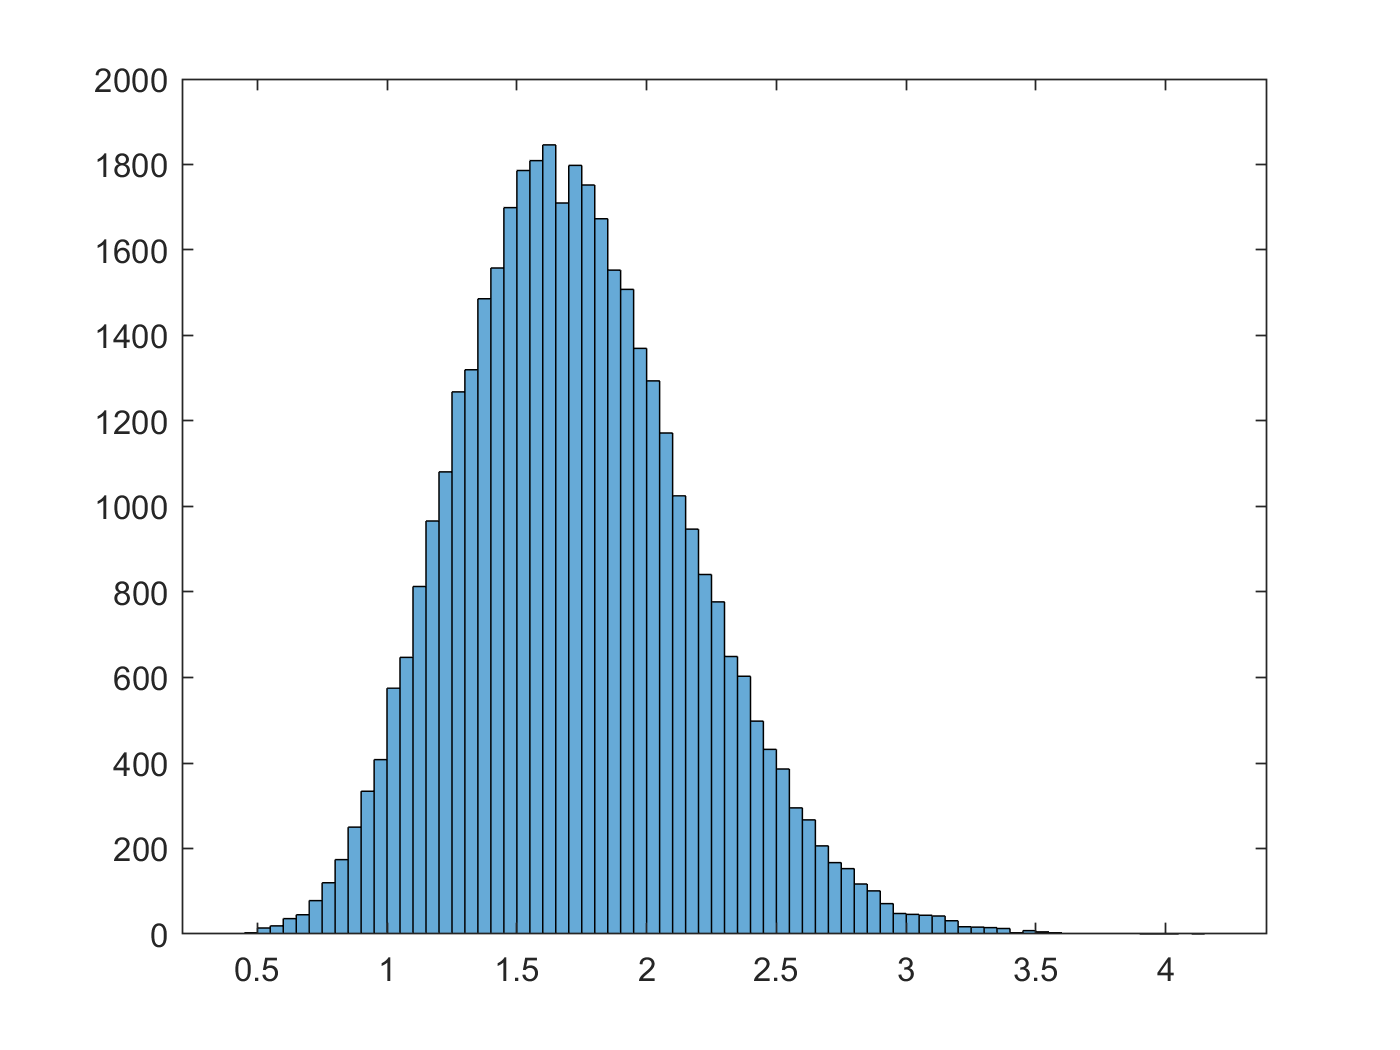

histogram(maxdiff)

max(max(maxdiff))

ans = 4.1681